# Retrieve Data from Deeplabcut

%Geoffrey 2026 - Ratliff*, Terral* et al 2026

%Update per mouse 07/22/25
Data_per_mouse=1;%assume 2 sessions per treatment per animals


% cd("G:\Ephy\homeCage\CNO_0.5mgkg")
% load('Parameters.mat')
% PathlistVeh=Inh_Dreadd.PathlistVeh;
% PathlistCNO=Inh_Dreadd.PathlistCNO;
% PathlistVeh=Exc_Dreadd.PathlistVeh;
% PathlistCNO=Exc_Dreadd.PathlistCNO;


%VEHICLE
for s=1:numel(PathlistVeh)
basepath=PathlistVeh{s};
cd(basepath)
basename=bz_BasenameFromBasepath(basepath);

load(basename + ".DeepLabCut.mat");

%%Total distance run by mice
WAKEVeh(s,1)=sum(deeplabcutOutput.WAKE(:,3));%intervals of time in wake not from deeplabcut but not accounting for camera start so you need to extract FirstCameraFrame
NREMVeh(s,1)=sum(deeplabcutOutput.NREM(:,3));%intervals of time in NREM

ProportionSleepinNestVeh(s,1)=deeplabcutOutput.ProportionSleepinNest;
ProportionWakeinNestVeh(s,1)=deeplabcutOutput.ProportionWakeinNest;
MeasureareaNest=deeplabcutOutput.MeasureareaNest;%in square mm - here need to check if it exist (=not too small)
MeasureareaCage=deeplabcutOutput.MeasureareaCage;
NestProportionVeh(s,1)=(MeasureareaNest/MeasureareaCage)*100;

Instdistance=deeplabcutOutput.Instdistance;%instantaneous distance run per frame in mm
InstdistanceWake=deeplabcutOutput.InstdistanceWake;
NREMindex=deeplabcutOutput.NREMindex;%frame index of sleep
InstdistanceNrem = Instdistance(NREMindex,1);
DistanceWakeVeh(s,1)=sum(InstdistanceWake,'omitnan')/1000;
DistanceNremVeh(s,1)=sum(InstdistanceNrem,'omitnan')/1000;

DurationInNestWakeVeh(s,1)=deeplabcutOutput.DurationInNestWake;
DurationInNestNremVeh(s,1)=deeplabcutOutput.DurationInNestNrem;

end

%CNO
for s=1:numel(PathlistCNO)
basepath=PathlistCNO{s};
cd(basepath)
basename=bz_BasenameFromBasepath(basepath);

load(basename + ".DeepLabCut.mat");

%%Total distance run by mice
WAKECNO(s,1)=sum(deeplabcutOutput.WAKE(:,3));%intervals of time in wake not from deeplabcut but not accounting for camera start so you need to extract FirstCameraFrame
NREMCNO(s,1)=sum(deeplabcutOutput.NREM(:,3));%intervals of time in NREM

ProportionSleepinNestCNO(s,1)=deeplabcutOutput.ProportionSleepinNest;
ProportionWakeinNestCNO(s,1)=deeplabcutOutput.ProportionWakeinNest;
MeasureareaNest=deeplabcutOutput.MeasureareaNest;%in square mm - here need to check if it exist (=not too small)
MeasureareaCage=deeplabcutOutput.MeasureareaCage;
NestProportionCNO(s,1)=(MeasureareaNest/MeasureareaCage)*100;

Instdistance=deeplabcutOutput.Instdistance;%instantaneous distance run per frame in mm
InstdistanceWake=deeplabcutOutput.InstdistanceWake;
NREMindex=deeplabcutOutput.NREMindex;%frame index of sleep
InstdistanceNrem = Instdistance(NREMindex,1);
DistanceWakeCNO(s,1)=sum(InstdistanceWake,'omitnan')/1000;
DistanceNremCNO(s,1)=sum(InstdistanceNrem,'omitnan')/1000;

DurationInNestWakeCNO(s,1)=deeplabcutOutput.DurationInNestWake;
DurationInNestNremCNO(s,1)=deeplabcutOutput.DurationInNestNrem;

end

## General figures

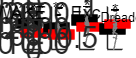

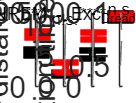

BOXPLOT=false;

conditions{1}='Veh';
conditions{2}='CNO';
STATS='paired';
YLABELS={'Total duration (sec)','Total distance (m)','Duration in Nest (sec)','Proportion time in nest'};

for S=1:2
    if S==1
%% STATE = WAKE
STATEVeh=WAKEVeh;DistSTATEVeh=DistanceWakeVeh;DurSTATEVeh=DurationInNestWakeVeh;PropSTATEnestVeh=ProportionWakeinNestVeh;
STATECNO=WAKECNO;DistSTATECNO=DistanceWakeCNO;DurSTATECNO=DurationInNestWakeCNO;PropSTATEnestCNO=ProportionWakeinNestCNO;
TITLE='WAKE - Exc_Dreadd';
    else
% %% STATE = NREM
STATEVeh=NREMVeh;DistSTATEVeh=DistanceNremVeh;DurSTATEVeh=DurationInNestNremVeh;PropSTATEnestVeh=ProportionSleepinNestVeh;
STATECNO=NREMCNO;DistSTATECNO=DistanceNremCNO;DurSTATECNO=DurationInNestNremCNO;PropSTATEnestCNO=ProportionSleepinNestCNO;
TITLE='NREM - Exc_Dreadd';
    end

% NestIdxVeh=find(NestProportionVeh>=15);%7/22/25
% NestIdxCNO=find(NestProportionCNO>=15);
NestIdxVeh=find(NestProportionVeh<15);%7/22/25
NestIdxCNO=find(NestProportionCNO<15);
if size(NestIdxVeh,1)~=size(DurSTATEVeh,1)||size(NestIdxCNO,1)~=size(DurSTATECNO,1)
    warning('nest too small or not existing - removed from analysis')
end

if ~isempty(NestIdxVeh)%7/22/25
   DurSTATEVeh(NestIdxVeh)=NaN;
   PropSTATEnestVeh(NestIdxVeh)=NaN;
end
if ~isempty(NestIdxCNO)
   DurSTATECNO(NestIdxCNO)=NaN;
   PropSTATEnestCNO(NestIdxCNO)=NaN;
end


fig = figure;

for ii=1:4
    if ii==1 %total duration spent in nest
        data1=STATEVeh;data2=STATECNO;
    elseif ii==2
        data1=DistSTATEVeh;data2=DistSTATECNO;
    elseif ii==3
        % data1=DurSTATEVeh(NestIdxVeh);data2=DurSTATECNO(NestIdxCNO);%7/22/25
        data1=DurSTATEVeh;data2=DurSTATECNO;
    elseif ii==4
        % data1=PropSTATEnestVeh(NestIdxVeh);data2=PropSTATEnestCNO(NestIdxCNO);
        data1=PropSTATEnestVeh;data2=PropSTATEnestCNO;
    end

%% to compile data per mouse
    if Data_per_mouse ==1
    MMM=[];m=0;JJJ=[];
    Nmice=size(data1,1)/2;%assume 2 sessions per treatment per animals
        for M=1:Nmice
            MM=[];JJ=[];
            MM=nanmean(data1(1+m:2+m,1),1);
            JJ=nanmean(data2(1+m:2+m,1),1);
            MMM=[MMM;MM];JJJ=[JJJ;JJ];
            m=m+2;
        end
        data1=MMM;
        data2=JJJ;
    end



subplot(1,4,ii)
if BOXPLOT
boxplot([data1,data2],'labels',conditions);
hold on
color = ['r','k']; 

h = findobj(gca,'Tag','Box'); 
h2 = findobj(gca,'Tag','Median'); h3=findobj('LineStyle','--'); set(h3, 'LineStyle','-');
for j=1:length(h) 
patch(get(h(j),'XData'),get(h(j),'YData'),color(j),'FaceAlpha',.2);
h2(j).Color=color(j);
h2(j).LineWidth=2;
end 

hold on
l = length(data1(:,1));
V1 = ones(l,1)*1.25;
V2 = ones(l,1)*1.75;

for j = 1:l
    plot([V1(j),V2(j)],[data1(j,1),data2(j,1)],'k')
end

box off
ylabel(YLABELS{ii})
hold on 
[pval,~]=STAT_paired_unpaired([data1,data2],'paired');

else

[~,datamean,dataSEM,pval]=MeanSEMgraph([data1,data2], conditions, YLABELS{ii}, {'k','r'},'paired');
if ii==4
    ylim([0.3 1])
end
end
sgtitle(TITLE) %give general title to all subplot
% titleFIG=['SleepOnsets_',TitleFig];
% cd('E:\Ephy\homeCage\CNO_0.5mgkg')
% savefig(titleFIG)
end
set(fig, 'Position', [500, 500, 1200, 500]);
end